## `ROBT403 HW3: Robot moving towards destination point with obstacle avoidance using ANN. `

## `Author: Andrey Yershov, NU 4th year Robotics and Mechatronics student `

First, the map was created using simple Graphical Editor and saved as .pbm. The map is then imported and converted to binaryOccupancyMap of dimensions 4 x 6 meters. binaryOccupancyMap is a part of Navigation Toolbox and is frequently used in Robotics applications with MATLAB.

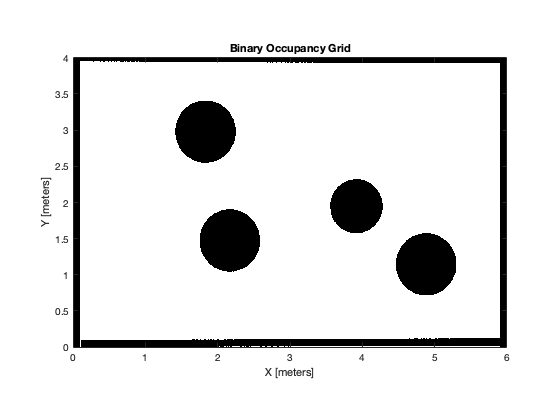

close all
clear
map1 = imread('mapI.pbm');
map = binaryOccupancyMap(map1, 200);
show(map)

Next, the Visualizer2D is used with the imported map and the robot with radius of 0.25m is created to be similar in dimension with the environment. Visualizer2D is a part of Robotics Toolbox in MATLAB. Its ability to show the robot's trajectory and a waypoint was used in order to help with the visualization of the task. From the same library, lidar was used to simulate the obstacle sensors. This has increased the accuracy of the algorithm compared with the overlap approach.

% set the Visualizer2D parameters
viz = Visualizer2D;
viz.robotRadius = 0.25;
viz.showTrajectory = true;
viz.mapName = 'map';
viz.hasWaypoints = true;

% create robot
R = 0.2;                                      % wheel radius (to the scale)
W = viz.robotRadius * 2;                      % wheelbase = robot radius * 2
robot = [R W];                                % robot physical characteristics for FK 

% set the obstacle sensors parameters
lidar = LidarSensor;
lidar.scanAngles = [-pi/3,-pi/9,0,pi/9,pi/3];  % five sensors
lidar.maxRange = 0.6;                          % -robot radius = 0.35m (to scale)
attachLidarSensor(viz,lidar);
waypoints = [5 3.5];                           % create the destination point


The moving to the destination loop works until the destination is reached. First, the direction is calculated in degrees (to understand easier). Then, the direction angle is normalized between -0.5 and 0.5 in order to be able to impact the wheels differently for steering to destination (so 0 is correct direction, no steering needed). Then, the sensor readings are collected to a matrix and normalized between 0.1 and 1 and the inverse is fed to the ANN. The inverse is used so that the closer obstacles will have more effect than the obstacles further. Bias of 0.2 was used in order to have the positive velocity consistently.

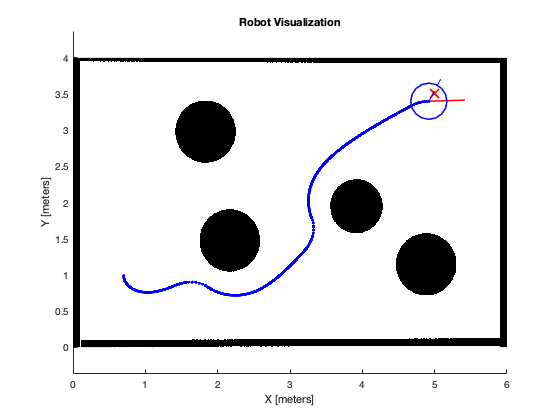

sampleTime = 0.01;
step = 1;
curPose = [0.7; 1; -pi/2];    % Initial pose (x y theta)
pose = curPose;

while((abs(waypoints(1)-curPose(1))>.1)||(abs(curPose(2)-waypoints(2))>.1))
    next_position = [0;0;0];
    pose = [pose next_position]; % concatenate next pose to the pose matrix
    
    % calculate the direction to target (degrees to understand easier)
    targetDir = rad2deg(atan2(waypoints(2)-curPose(2),...
                waypoints(1)-curPose(1)) - curPose(3));
    
    % make the direction circulat in -180 - 180 degrees
    if targetDir > 180
        targetDir = targetDir - 360;  
    elseif targetDir < -180
        targetDir =  360 + targetDir;
    end
    
    % normalize dir -0.5 - 0.5 for ANN
    % positive --> turn left
    % negative --> turn right
    targetDir = ((targetDir+180)/(2*180)) - 0.5;
    
    % inputs from sensor
    ranges = (lidar(curPose) - viz.robotRadius); % inputs in range 0 - 0.25m
    
    % normalize to 0.1 - 1 for ANN
    rangesN = (ranges+0.1)/0.4;
    
    % create ANN
    % inputs matrix --> [dir, CC, CR, CL, CRR, CLL]
    inputs = [targetDir, 1/rangesN(3), 1/rangesN(2),...
              1/rangesN(4), 1/rangesN(1), 1/rangesN(5)];
    
    % change NaN inputs to 0
    inputs (isnan(inputs)) = 0;
    
    % ANN
    weights = [-0.9, -0.15, 0, 0.35, 0, 0.5;  % left wheel
                0.9, -0.15, 0.35, 0, 0.5, 0]; % right wheel
    bias = 0.2;
    activation = (weights * inputs.') + bias;    
    leftW = activation(1)*30;
    rightW = activation(2)*30;
    
    % calc FK
    [v, y, w] = FK(robot,leftW,rightW);
    
    % calculate the velocity of the robot relative to the map
    velocity = rtm([v; y; w], curPose);
    
    % calculate next pose
    pose(:,step+1) = curPose + velocity * sampleTime;
    
    % move toward waypoint
    viz(pose(:,step+1), waypoints, ranges)
    
    % iterate the counter and current pose variable
    step = step + 1;
    curPose = pose(:,step);
end

Forward Kinematics and Roto-translation functions

function [v, y, w] = FK(robot, LW, RW)
    y = 0; % zero lateral velocity (for rtm)
    v = 0.5 * robot(1) * (LW + RW);
    w = (RW - LW) * robot(1)/robot(2);
end

function velocity = rtm(V, pose)
    angle = pose(3);
    velocity = [cos(angle) -sin(angle) 0; sin(angle) cos(angle)  0; 0 0 1]*V;
end